% Read the image
image = imread('img1.jpg');

% Convert image to grayscale
gray_image = rgb2gray(image);

% Apply Gaussian smoothing to reduce noise
smoothed_image = imgaussfilt(gray_image, 2);

% Apply edge detection (Canny edge detector)
edges = edge(smoothed_image, 'Canny', [0.1 0.2], 3);

% Close gaps in edges
se = strel('line', 3, 90); % Adjust the length of the line according to your image
edges_closed = imclose(edges, se);

% Perform Hough Transform
[H, theta, rho] = hough(edges_closed);

% Find peaks in the Hough Transform
peaks = houghpeaks(H, 50, 'Threshold', 0.3 * max(H(:)));

% Retrieve lines from the peaks
lines = houghlines(edges_closed, theta, rho, peaks);

% Display the original image with detected lines
figure, imshow(image);

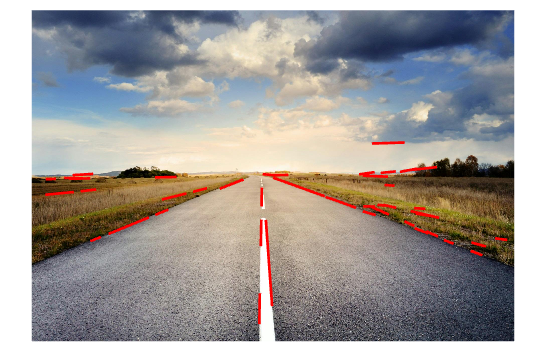

hold on;
% Plot the lines on the image
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'red');
end
hold off;